# This is a quick and dirty script I made to do some really early comparisons of COM data from other scripted analyses. It may or may not be helpful, but I wanted to include it.

2022/04/22 - trentondwirth at gmail dot com

#### Nuke'em

close all
clearvars
restoredefaultpath

#### Get your basic paths right

npyReaderPath = 'your path here'; % get your path to the npy reader

addpath(genpath(npyReaderPath));


Read Data

fmc_COM_XYZ = readNPY('totalBodyCOM_frame_XYZ_AaronFinal.npy');

quali_COM_XYZ = readNPY('qualisys_totalBodyCOM_frame_XYZ_AaronFinal.npy');

Prep and assess natural stance

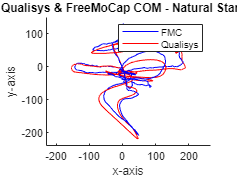

fmc_start_natural = 9500; % 60 fps
fmc_end_natural = 11980;

quali_start_natural = 58355; % 300 fps
quali_end_natural = 70755;

fmc_COM_XYZ_natural = fmc_COM_XYZ(fmc_start_natural:fmc_end_natural,:);
fmc_COM_XYZ_natural = fmc_COM_XYZ_natural - fmc_COM_XYZ_natural(1,:);

quali_COM_XYZ_natural_fullSamp = quali_COM_XYZ(quali_start_natural:quali_end_natural,:);
quali_COM_XYZ_natural_downSamp = downsample(quali_COM_XYZ_natural_fullSamp,5);
quali_COM_XYZ_natural_downSamp = quali_COM_XYZ_natural_downSamp - quali_COM_XYZ_natural_downSamp(1,:); 

figure(randi(20000))
hold on;
title('Qualisys & FreeMoCap COM - Natural Stance')
plot3(fmc_COM_XYZ_natural(:,1),fmc_COM_XYZ_natural(:,2),fmc_COM_XYZ_natural(:,3),'b');
plot3(quali_COM_XYZ_natural_downSamp(:,1),quali_COM_XYZ_natural_downSamp(:,2),quali_COM_XYZ_natural_downSamp(:,3),'r');
axis equal
xlabel 'x-axis'
ylabel 'y-axis'
zlabel 'z-axis'
legend('FMC','Qualisys')
hold off



RMSE_natural_x = sqrt(mean((quali_COM_XYZ_natural_downSamp(:,1) - fmc_COM_XYZ_natural(:,1)).^2))  

RMSE_natural_x = 5.9141

RMSE_natural_y = sqrt(mean((quali_COM_XYZ_natural_downSamp(:,2) - fmc_COM_XYZ_natural(:,2)).^2))  

RMSE_natural_y = 9.4000

RMSE_natural_z = sqrt(mean((quali_COM_XYZ_natural_downSamp(:,3) - fmc_COM_XYZ_natural(:,3)).^2)) 

RMSE_natural_z = 15.5771


rmse_vect_nat = [RMSE_natural_x,RMSE_natural_y,RMSE_natural_z];
vect_magnitude_natural = norm(rmse_vect_nat)

vect_magnitude_natural = 19.1307

prep and assess left legged stance

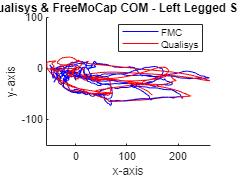

fmc_start_left_leg = 13008;
fmc_end_left_leg = 15156;


quali_start_left_leg = 75890; 
quali_end_left_leg = 86630;


fmc_COM_XYZ_left_leg = fmc_COM_XYZ(fmc_start_left_leg:fmc_end_left_leg,:);
fmc_COM_XYZ_left_leg = fmc_COM_XYZ_left_leg - fmc_COM_XYZ_left_leg(1,:);

quali_COM_XYZ_left_leg_fullSamp = quali_COM_XYZ(quali_start_left_leg:quali_end_left_leg,:);
quali_COM_XYZ_left_leg_downSamp = downsample(quali_COM_XYZ_left_leg_fullSamp,5);
quali_COM_XYZ_left_leg_downSamp = quali_COM_XYZ_left_leg_downSamp - quali_COM_XYZ_left_leg_downSamp(1,:); 

figure(randi(20000))
hold on;
title('Qualisys & FreeMoCap COM - Left Legged Stance')
plot3(fmc_COM_XYZ_left_leg(:,1),fmc_COM_XYZ_left_leg(:,2),fmc_COM_XYZ_left_leg(:,3),'b');
plot3(quali_COM_XYZ_left_leg_downSamp(:,1),quali_COM_XYZ_left_leg_downSamp(:,2),quali_COM_XYZ_left_leg_downSamp(:,3),'r');
axis equal
xlabel 'x-axis'
ylabel 'y-axis'
zlabel 'z-axis'
legend('FMC','Qualisys')
hold off



RMSE_left_leg_x = sqrt(mean((quali_COM_XYZ_left_leg_downSamp(:,1) - fmc_COM_XYZ_left_leg(:,1)).^2))  

RMSE_left_leg_x = 10.7737

RMSE_left_leg_y = sqrt(mean((quali_COM_XYZ_left_leg_downSamp(:,2) - fmc_COM_XYZ_left_leg(:,2)).^2))  

RMSE_left_leg_y = 8.2550

RMSE_left_leg_z = sqrt(mean((quali_COM_XYZ_left_leg_downSamp(:,3) - fmc_COM_XYZ_left_leg(:,3)).^2)) 

RMSE_left_leg_z = 16.0848


rmse_vect_LL = [RMSE_left_leg_x,RMSE_left_leg_y,RMSE_left_leg_z];
vect_magnitude_LL = norm(rmse_vect_LL)

vect_magnitude_LL = 21.0461

prep and assess right legged stance

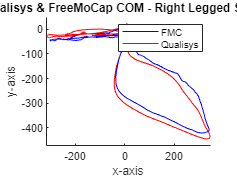

fmc_start_right_leg = 16000;
fmc_end_right_leg = 17419;


quali_start_right_leg = 90890; 
quali_end_right_leg = 97985;


fmc_COM_XYZ_right_leg = fmc_COM_XYZ(fmc_start_right_leg:fmc_end_right_leg,:);
fmc_COM_XYZ_right_leg = fmc_COM_XYZ_right_leg - fmc_COM_XYZ_right_leg(1,:);

quali_COM_XYZ_right_leg_fullSamp = quali_COM_XYZ(quali_start_right_leg:quali_end_right_leg,:);
quali_COM_XYZ_right_leg_downSamp = downsample(quali_COM_XYZ_right_leg_fullSamp,5);
quali_COM_XYZ_right_leg_downSamp = quali_COM_XYZ_right_leg_downSamp - quali_COM_XYZ_right_leg_downSamp(1,:); 

figure(randi(20000))
hold on;
title('Qualisys & FreeMoCap COM - Right Legged Stance')
plot3(fmc_COM_XYZ_right_leg(:,1),fmc_COM_XYZ_right_leg(:,2),fmc_COM_XYZ_right_leg(:,3),'b');
plot3(quali_COM_XYZ_right_leg_downSamp(:,1),quali_COM_XYZ_right_leg_downSamp(:,2),quali_COM_XYZ_right_leg_downSamp(:,3),'r');
axis equal
xlabel 'x-axis'
ylabel 'y-axis'
zlabel 'z-axis'
legend('FMC','Qualisys')
hold off



RMSE_right_leg_x = sqrt(mean((quali_COM_XYZ_right_leg_downSamp(:,1) - fmc_COM_XYZ_right_leg(:,1)).^2))  

RMSE_right_leg_x = 13.0885

RMSE_right_leg_y = sqrt(mean((quali_COM_XYZ_right_leg_downSamp(:,2) - fmc_COM_XYZ_right_leg(:,2)).^2))  

RMSE_right_leg_y = 13.0813

RMSE_right_leg_z = sqrt(mean((quali_COM_XYZ_right_leg_downSamp(:,3) - fmc_COM_XYZ_right_leg(:,3)).^2)) 

RMSE_right_leg_z = 12.6749


rmse_vect_RL = [RMSE_right_leg_x,RMSE_right_leg_y,RMSE_right_leg_z];
vect_magnitude_RL = norm(rmse_vect_RL)

vect_magnitude_RL = 22.4295

Create a plot of all three comparisons (top down view, and then side view)

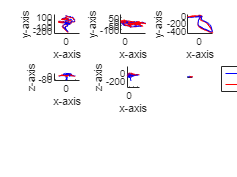



subplot(3,3,1)
hold on;
plot3(fmc_COM_XYZ_natural(:,1),fmc_COM_XYZ_natural(:,2),fmc_COM_XYZ_natural(:,3),'b');
plot3(quali_COM_XYZ_natural_downSamp(:,1),quali_COM_XYZ_natural_downSamp(:,2),quali_COM_XYZ_natural_downSamp(:,3),'r');
axis equal
xlabel 'x-axis'
ylabel 'y-axis'
zlabel 'z-axis'
view([0,90]);

subplot(3,3,2)
hold on;
plot3(fmc_COM_XYZ_left_leg(:,1),fmc_COM_XYZ_left_leg(:,2),fmc_COM_XYZ_left_leg(:,3),'b');
plot3(quali_COM_XYZ_left_leg_downSamp(:,1),quali_COM_XYZ_left_leg_downSamp(:,2),quali_COM_XYZ_left_leg_downSamp(:,3),'r');
axis equal
xlabel 'x-axis'
ylabel 'y-axis'
zlabel 'z-axis'
view([0,90]);


subplot(3,3,3)
hold on;
plot3(fmc_COM_XYZ_right_leg(:,1),fmc_COM_XYZ_right_leg(:,2),fmc_COM_XYZ_right_leg(:,3),'b');
plot3(quali_COM_XYZ_right_leg_downSamp(:,1),quali_COM_XYZ_right_leg_downSamp(:,2),quali_COM_XYZ_right_leg_downSamp(:,3),'r');
axis equal
xlabel 'x-axis'
ylabel 'y-axis'
zlabel 'z-axis'
view([0,90]);

subplot(3,3,4)
hold on;
plot3(fmc_COM_XYZ_natural(:,1),fmc_COM_XYZ_natural(:,2),fmc_COM_XYZ_natural(:,3),'b');
plot3(quali_COM_XYZ_natural_downSamp(:,1),quali_COM_XYZ_natural_downSamp(:,2),quali_COM_XYZ_natural_downSamp(:,3),'r');
axis equal
xlabel 'x-axis'
ylabel 'y-axis'
zlabel 'z-axis'
view([0,0]);

subplot(3,3,5)
hold on;
plot3(fmc_COM_XYZ_left_leg(:,1),fmc_COM_XYZ_left_leg(:,2),fmc_COM_XYZ_left_leg(:,3),'b');
plot3(quali_COM_XYZ_left_leg_downSamp(:,1),quali_COM_XYZ_left_leg_downSamp(:,2),quali_COM_XYZ_left_leg_downSamp(:,3),'r');
axis equal
xlabel 'x-axis'
ylabel 'y-axis'
zlabel 'z-axis'
view([0,0]);


subplot(3,3,6)
hold on;
plot3(fmc_COM_XYZ_right_leg(:,1),fmc_COM_XYZ_right_leg(:,2),fmc_COM_XYZ_right_leg(:,3),'b');
plot3(quali_COM_XYZ_right_leg_downSamp(:,1),quali_COM_XYZ_right_leg_downSamp(:,2),quali_COM_XYZ_right_leg_downSamp(:,3),'r');
axis equal
xlabel 'x-axis'
ylabel 'y-axis'
zlabel 'z-axis'
view([0,0]);
legend('FreeMoCap','Qualisys')
box off

hold off